# sub-12

This code begins by importing raw SEEG data and converting to Fieldtrip format. 

It then edit the SEEG channel labels, inspects the SEEG data, and remove any bad channels.

Following this, the code redefines resting, 0-back, 1-back and 2-back blocks using TRIG or Event channel signals.   

## Set working directory

clc;clear;close all;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\fieldtrip-20231220;
ft_defaults;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\iEEGPrep
iEEGPrep_initial;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\neuracle-eegfile-reader-master
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function
cd  Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS;
subID = 'sub-12';
cd(fullfile(subID, 'ieeg'));

## Import SEEG data and edit channel labels

% Import SEEG data into matlab using fieldtrip style
evtfile = [subID, '_task-nback_run-1_evt.bdf'];
iEEGfile = [subID, '_task-nback_run-1_ieeg.bdf'];
[Data, Event] = f_readbdf(iEEGfile, evtfile);

BDF+ file format detected, the BDF Annotation channel will be skipped when reading data
processing channel { 'TA1' 'TA2' 'TA3' 'TA4' 'TA5' 'TA6' 'TA7' 'TA8' 'TA9' 'TA10' 'TA11' 'TA12' 'TB1' 'TB2' 'TB3' 'TB4' 'TB5' 'TB6' 'TB7' 'TB8' 'TB9' 'TB10' 'TB11' 'TB12' 'TI1' 'TI2' 'TI3' 'TI4' 'TI5' 'TI6' 'TI7' 'TI8' 'TA'1' 'TA'2' 'TA'3' 'TA'4' 'TA'5' 'TA'6' 'TA'7' 'TA'8' 'TA'9' 'TA'10' 'TA'11' 'TA'12' 'TB'1' 'TB'2' 'TB'3' 'TB'4' 'TB'5' 'TB'6' 'TB'7' 'TB'8' 'TB'9' 'TB'10' 'TB'11' 'TB'12' 'TI'1' 'TI'2' 'TI'3' 'TI'4' 'TI'5' 'TI'6' 'TI'7' 'TI'8' 'TI'9' 'TI'10' 'B'1' 'B'2' 'B'3' 'B'4' 'B'5' 'B'6' 'B'7' 'B'8' 'B'9' 'B'10' 'FU'1' 'FU'2' 'FU'3' 'FU'4' 'FU'5' 'FU'6' 'FU'7' 'FU'8' 'FU'9' 'FU'10' 'FU'11' 'FU'12' 'F'1' 'F'2' 'F'3' 'F'4' 'F'5' 'F'6' 'F'7' 'F'8' 'F'9' 'F'10' 'F'11' 'F'12' }
reading and preprocessing
reading and preprocessing trial 1 from 1

the call to "ft_preprocessing" took 30 seconds


## Remove bad channels

badChan = {'-TA1', '-TA11', '-TA12', '-TB1', '-TB2', '-TB12', '-TI''10' '-TA''1', '-TA''2', '-FU''12', '-FU''12'};
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 2 seconds


## Inspects SEEG signals

BPfreq = [1, 120];
DataPrep = f_filter_bandpass(Data, BPfreq);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 16 seconds


RSfreq = 250;
DataPrep = f_filter_resample(DataPrep, RSfreq);

the input is raw data with 90 channels and 1 trials
the call to "ft_selectdata" took 0 seconds
resampling data
resampling data in trial 1 from 1

original sampling rate = 2000 Hz
new sampling rate = 250 Hz
the call to "ft_resampledata" took 6 seconds


chanGroups = f_chanGroup(DataPrep.label);
refMethod = 'CommonAverage';
DataPrep = f_reref_SEEG(DataPrep, refMethod, chanGroups);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


the input is raw data with 90 channels and 1 trials


detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


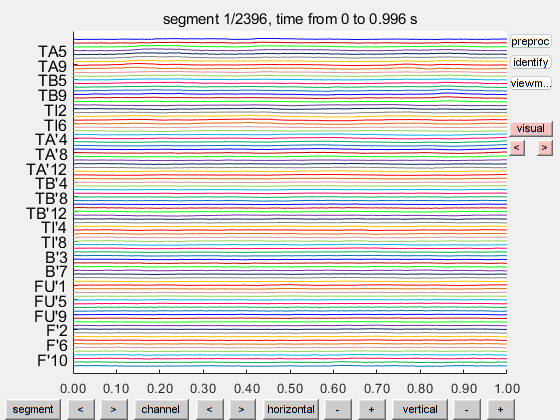

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg = [];
cfg.viewmode = 'vertical';
ft_databrowser(cfg, DataPrep);

## Redefine the resting block

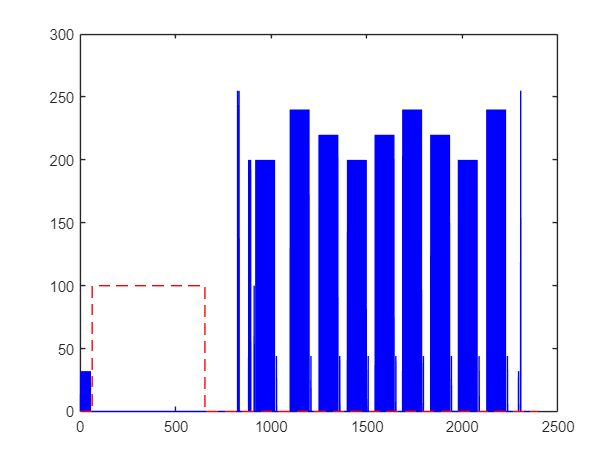

fsample = Data.fsample;
rsValue = 100;
rsStart = 105077;
rsStart = rsStart + ceil(10*fsample);
rsEnd = rsStart + ceil(10*60*fsample-10*fsample);
rsPointer = zeros(size(Event));
rsPointer(rsStart:rsEnd) = 1;
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, rsValue*rsPointer, '--r');
hold off;

% Construct data
rsSignals = Data.trial{1}(:, rsStart:rsEnd);
sampleinfo = [1, size(rsSignals, 2)];
rsTime = Data.time{1}(rsStart:rsEnd);
rsData.cfg = Data.cfg;
rsData.fsample = fsample;
rsData.label = Data.label;
rsData.hdr = Data.hdr;
rsData.trial{1} = rsSignals;
rsData.time{1} = rsTime;
rsData.sampleinfo = sampleinfo;
save([subID, '_task-resting_run-1_ieeg.mat'], 'rsData');
disp('******************************************************');

******************************************************


## Redefine the 0-back blocks

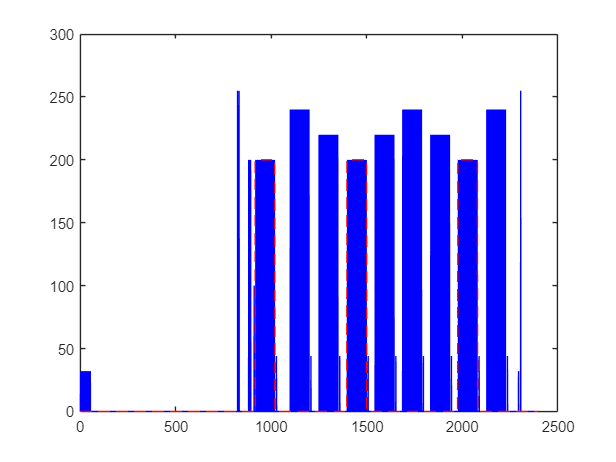

EventValue = unique(Event);
nb0Value = EventValue(5);
nb0Pointer = Event == nb0Value;
nb0Start = find(diff(nb0Pointer)==1);
nb0Start(nb0Start<1820700) = [];
nb0End = find(diff(nb0Pointer)==-1);
nb0End(nb0End<1820700) = [];
nb0Pointer = zeros(size(Event));
for nn = 1:length(nb0Start)
    nb0Pointer(nb0Start(nn)-ceil(3*fsample):nb0End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb0Value*nb0Pointer, '--r');
hold off;

% Construct data
nb0Start = find(diff(nb0Pointer)==1);
nb0End = find(diff(nb0Pointer)==-1);
nb0Data.cfg = Data.cfg;
nb0Data.fsample = fsample;
nb0Data.label = Data.label;
nb0Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb0Start(nRun), nb0End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb0Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb0Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb0Data.sampleinfo(nRun, :) = sampleinfo;
    nb0Data.time{nRun} = nb0Time;
    nb0Data.trial{nRun} = nb0Signal;
end
save([subID, '_task-0back_run-1_ieeg.mat'], 'nb0Data', 'TRIG');
disp('******************************************');

******************************************


## Redefine the 1-back blocks

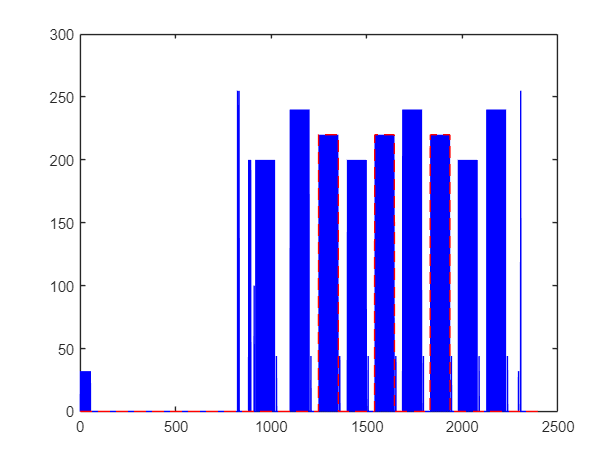

nb1Value = EventValue(6);
nb1Pointer = Event == nb1Value;
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Pointer = zeros(size(Event));
for nn = 1:length(nb1Start)
    nb1Pointer(nb1Start(nn)-ceil(3*fsample):nb1End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb1Value*nb1Pointer, '--r');
hold off;

% Construct data
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Data.cfg = Data.cfg;
nb1Data.fsample = fsample;
nb1Data.label = Data.label;
nb1Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb1Start(nRun), nb1End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb1Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb1Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb1Data.sampleinfo(nRun, :) = sampleinfo;
    nb1Data.time{nRun} = nb1Time;
    nb1Data.trial{nRun} = nb1Signal;
end
save([subID, '_task-1back_run-1_ieeg.mat'], 'nb1Data', 'TRIG');
disp('*************************************');

*************************************


## Redefine the 2-back blocks

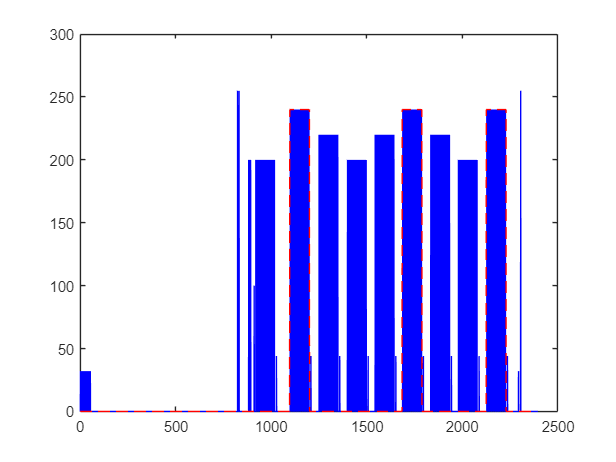

nb2Value = EventValue(7);
nb2Pointer = Event == nb2Value;
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Pointer = zeros(size(Event));
for nn = 1:length(nb2Start)
    nb2Pointer(nb2Start(nn)-ceil(3*fsample):nb2End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb2Value*nb2Pointer, '--r');
hold off;

% Construct data
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Data.cfg = Data.cfg;
nb2Data.fsample = fsample;
nb2Data.label = Data.label;
nb2Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb2Start(nRun), nb2End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb2Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb2Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb2Data.sampleinfo(nRun, :) = sampleinfo;
    nb2Data.time{nRun} = nb2Time;
    nb2Data.trial{nRun} = nb2Signal;
end
save([subID, '_task-2back_run-1_ieeg.mat'], 'nb2Data', 'TRIG');